*Will Reynolds (will.reynolds@mclaren.com), 2017*

# Kalman Filter Tutorial

This tutorial will first show you the value of the simplest Kalman filter, then walk through the terminology and the equations used for the rest of this tutorial. Once you are comfortable with the general approach of a linear Kalman filter (KF) and familiar with the terms, the next filter algorithms will be introduced and demonstrated in turn.

# Setting Up a Simple Tracking Problem

In order to show the value of the Kalman filter, let's look at a very simple example; a train moving along a straight track at constant velocity. We wish to estimate the states of the train every $\mathrm{dt}$ seconds. I am going to choose the following state vector, $x$, to define the system behaviour at each time step, $k$:

$x_k = \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$ , where $p$ is position along the track (m), and $v$ is velocity at which the train is moving (m/s). Given our understanding of the system dynamics, we can say that $p_{k+1} = p_{k} + v_k.\mathrm{dt}$ and $v_{k+1} = v_k$. This can be written as the following matrix algebra equation.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1}$$


Now, in almost any situation, our state update will not be this idealised. We will typically have random disturbances acting on our system, which is called **process noise**. For a train, this could be small changes in speed caused by wind buffeting. In this example, we are modelling this noise as a Gaussian random variable, $v_k$, centred around 0m/s, with variance 0.01m/s.


$$x_{k} = F.x_{k-1}=  \left[ \begin{array}{cc}
1 & \mathrm{dt}\\
0 & 1\\
\end{array} \right]. x_{k-1} + v_k$$


The measurement which we have available to us is the position of the train. This measurement, $y_k$, can therefore be written in matrix algebra as:


$$y_k = H.x_k = \left[ \begin{array}{cc}
1 & 0\\
\end{array} \right].  \left[ \begin{array}{c}
p_k\\
v_k\\
\end{array} \right]$$
 

Again, however, it is not likely that a measurement will be perfect. Typically, there will at least be electromagnetic noise acting on the signal. Any noise on the measurement is called, imaginatively, **measurement noise**. In this example, we are modelling this noise as a Gaussian random variable, $w_k$, centred around 0m, with variance 0.1m.

The true initial confitions at time $k=0$ are $x_0 = \left[ \begin{array}{c}
p_0\\
v_0\\
\end{array} \right] = \left[ \begin{array}{c}
0\\
10\\
\end{array} \right]$. However, we are going to start with the erroneous estimate of $\hat{x}_0 = \left[ \begin{array}{c}
0\\
5\\
\end{array} \right]$ to make things more interesting.

# Demonstrating the Value

So, we have now set up the problem. We have a train getting buffeted with wind moving at roughly 10m/s along a straight track with noisy measurements of its position. Let's take a look at tracking its position and velocity. Let's first off look at two extremes of simplistic tracking methods; just using a model, and just using measurements.

Using just the model, we end up being affected by the initial conditions hugely and have no hope of closing the error in position or velocity. 

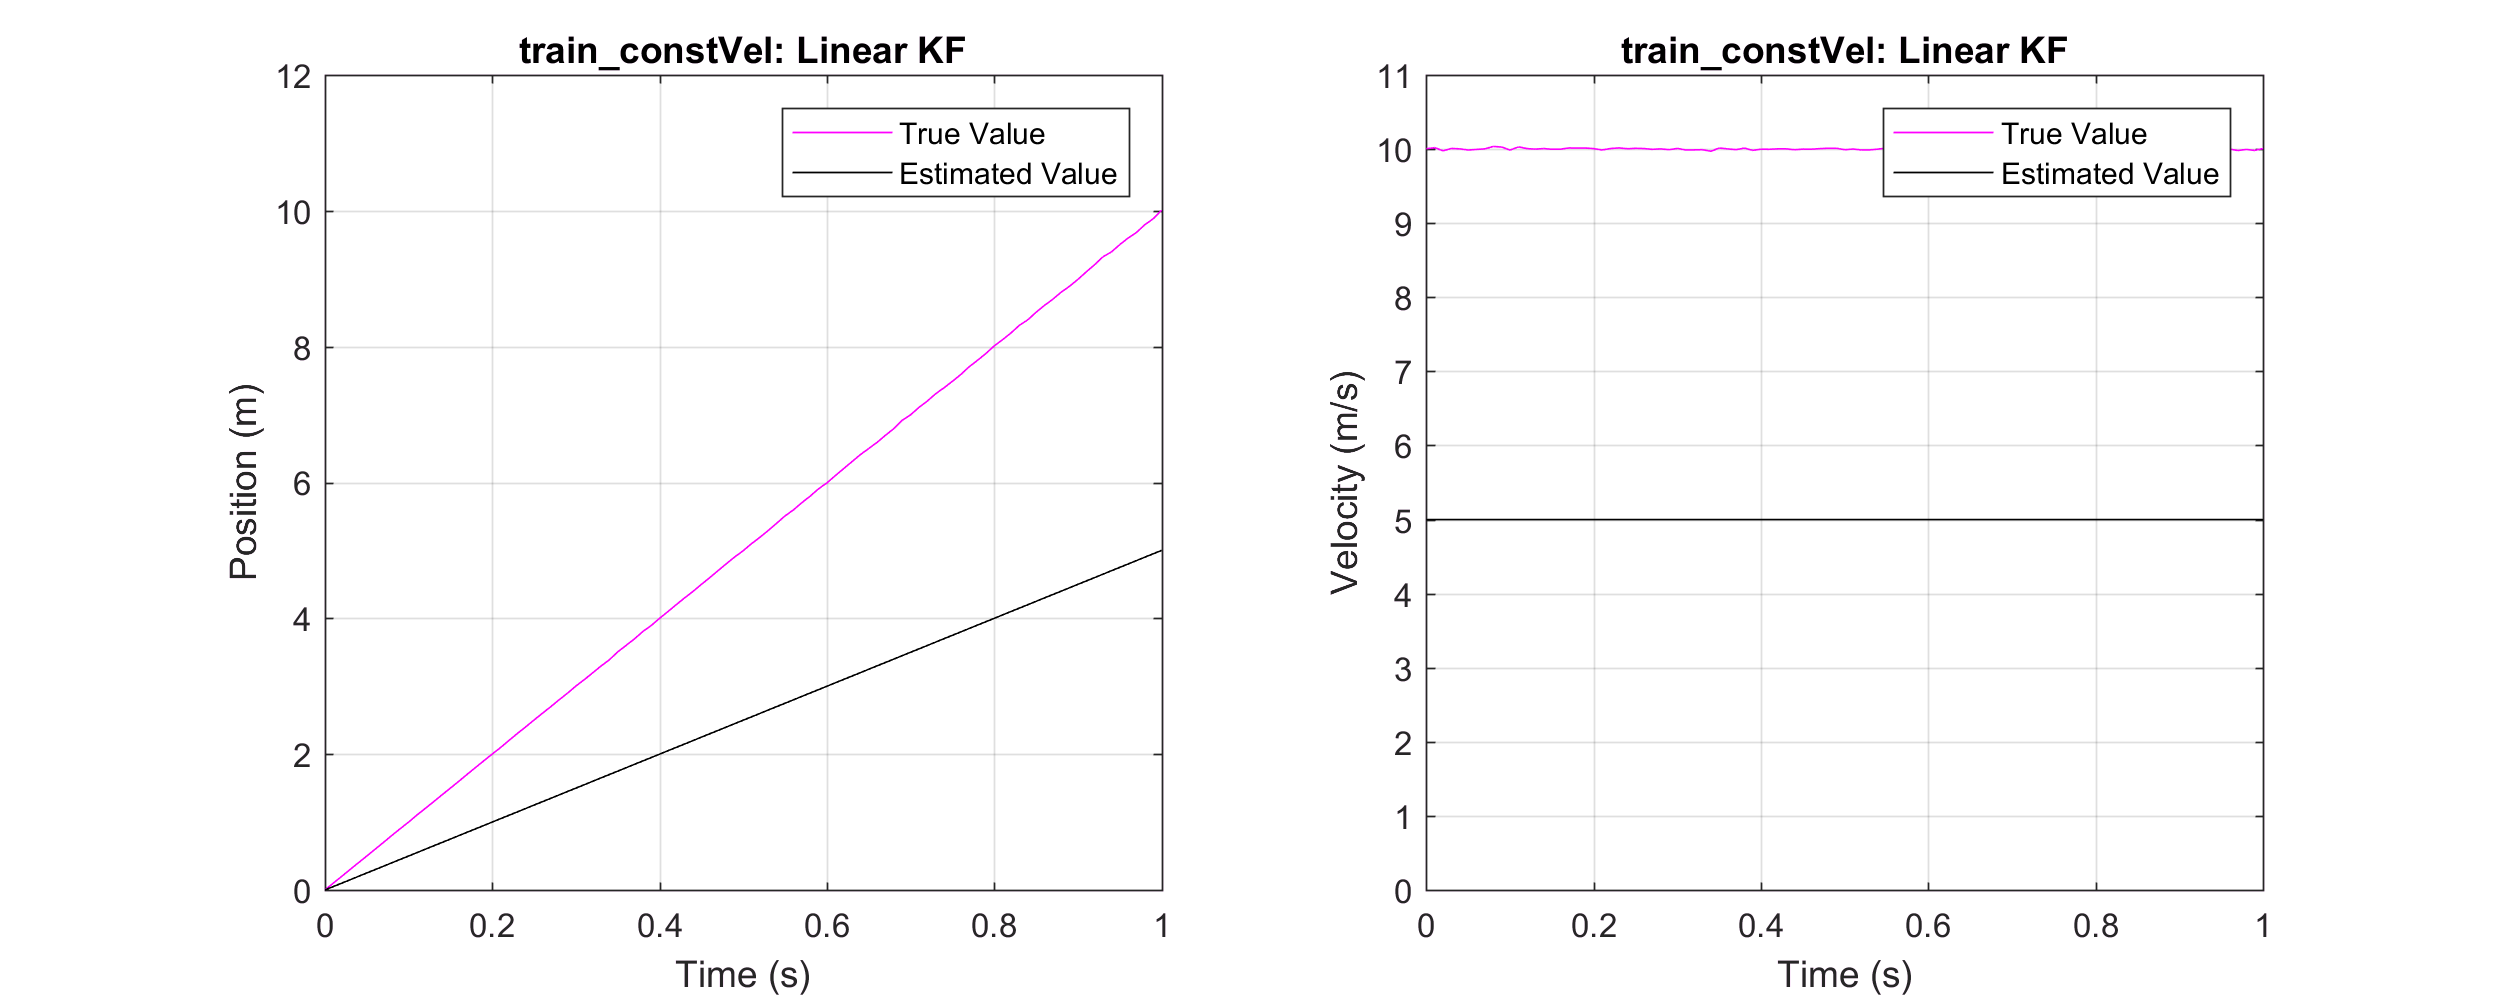

addpath(genpath(pwd))
open('ModelOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

Using just the measurements, we end up at the mercy of the large measurement noise levels and have to infer velocity from this noisy measurement, giving us huge errors in velocity.

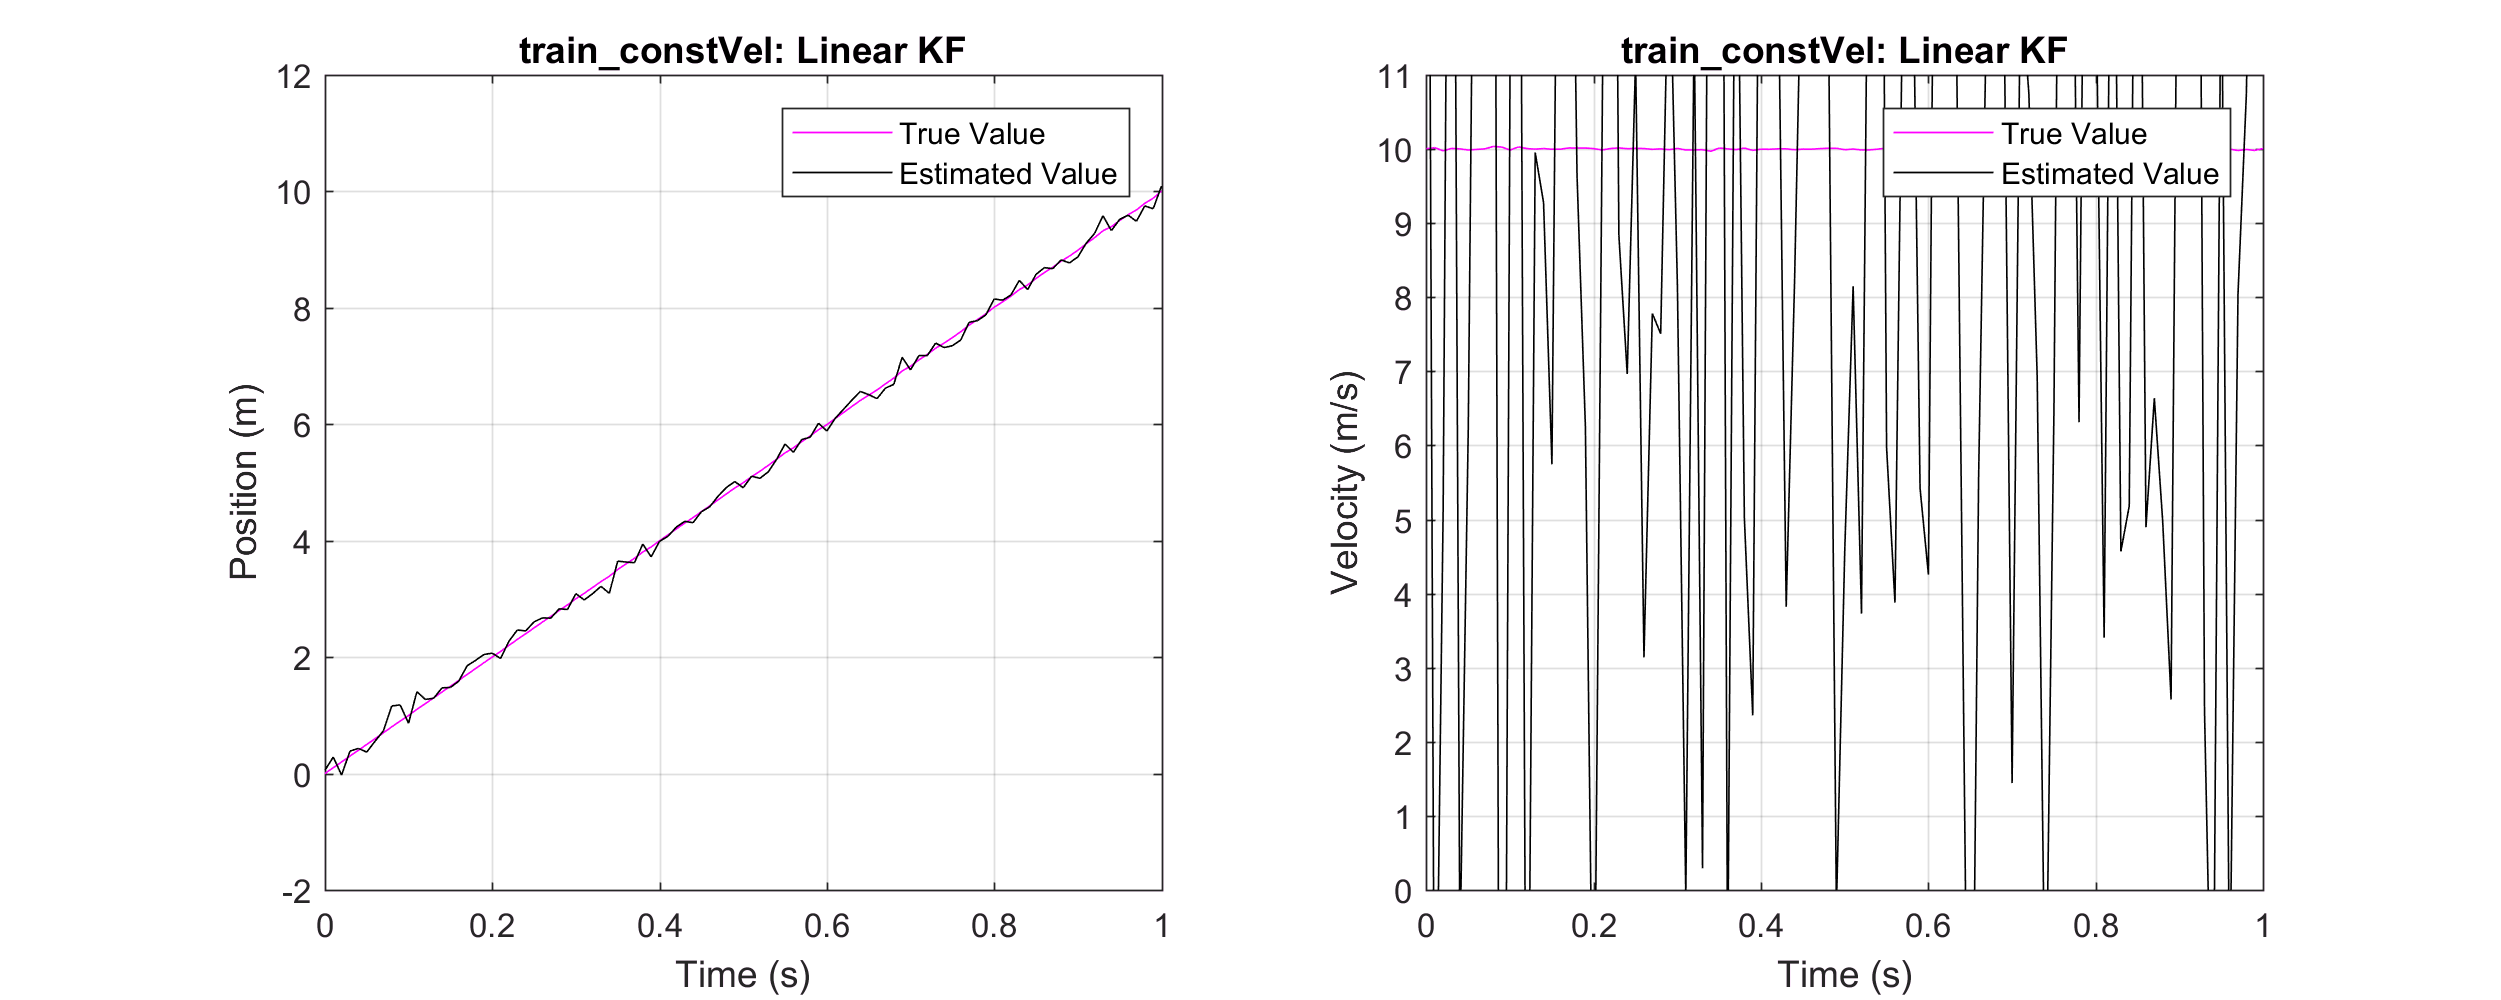

open('MeasurementOnly.fig')
set(gcf,'Position',[0 0 1000 400]);

However, if we implement a simple linear Kalman filter, using our imperfect model of the system and our noisy position measurements, we are able to achieve the following:

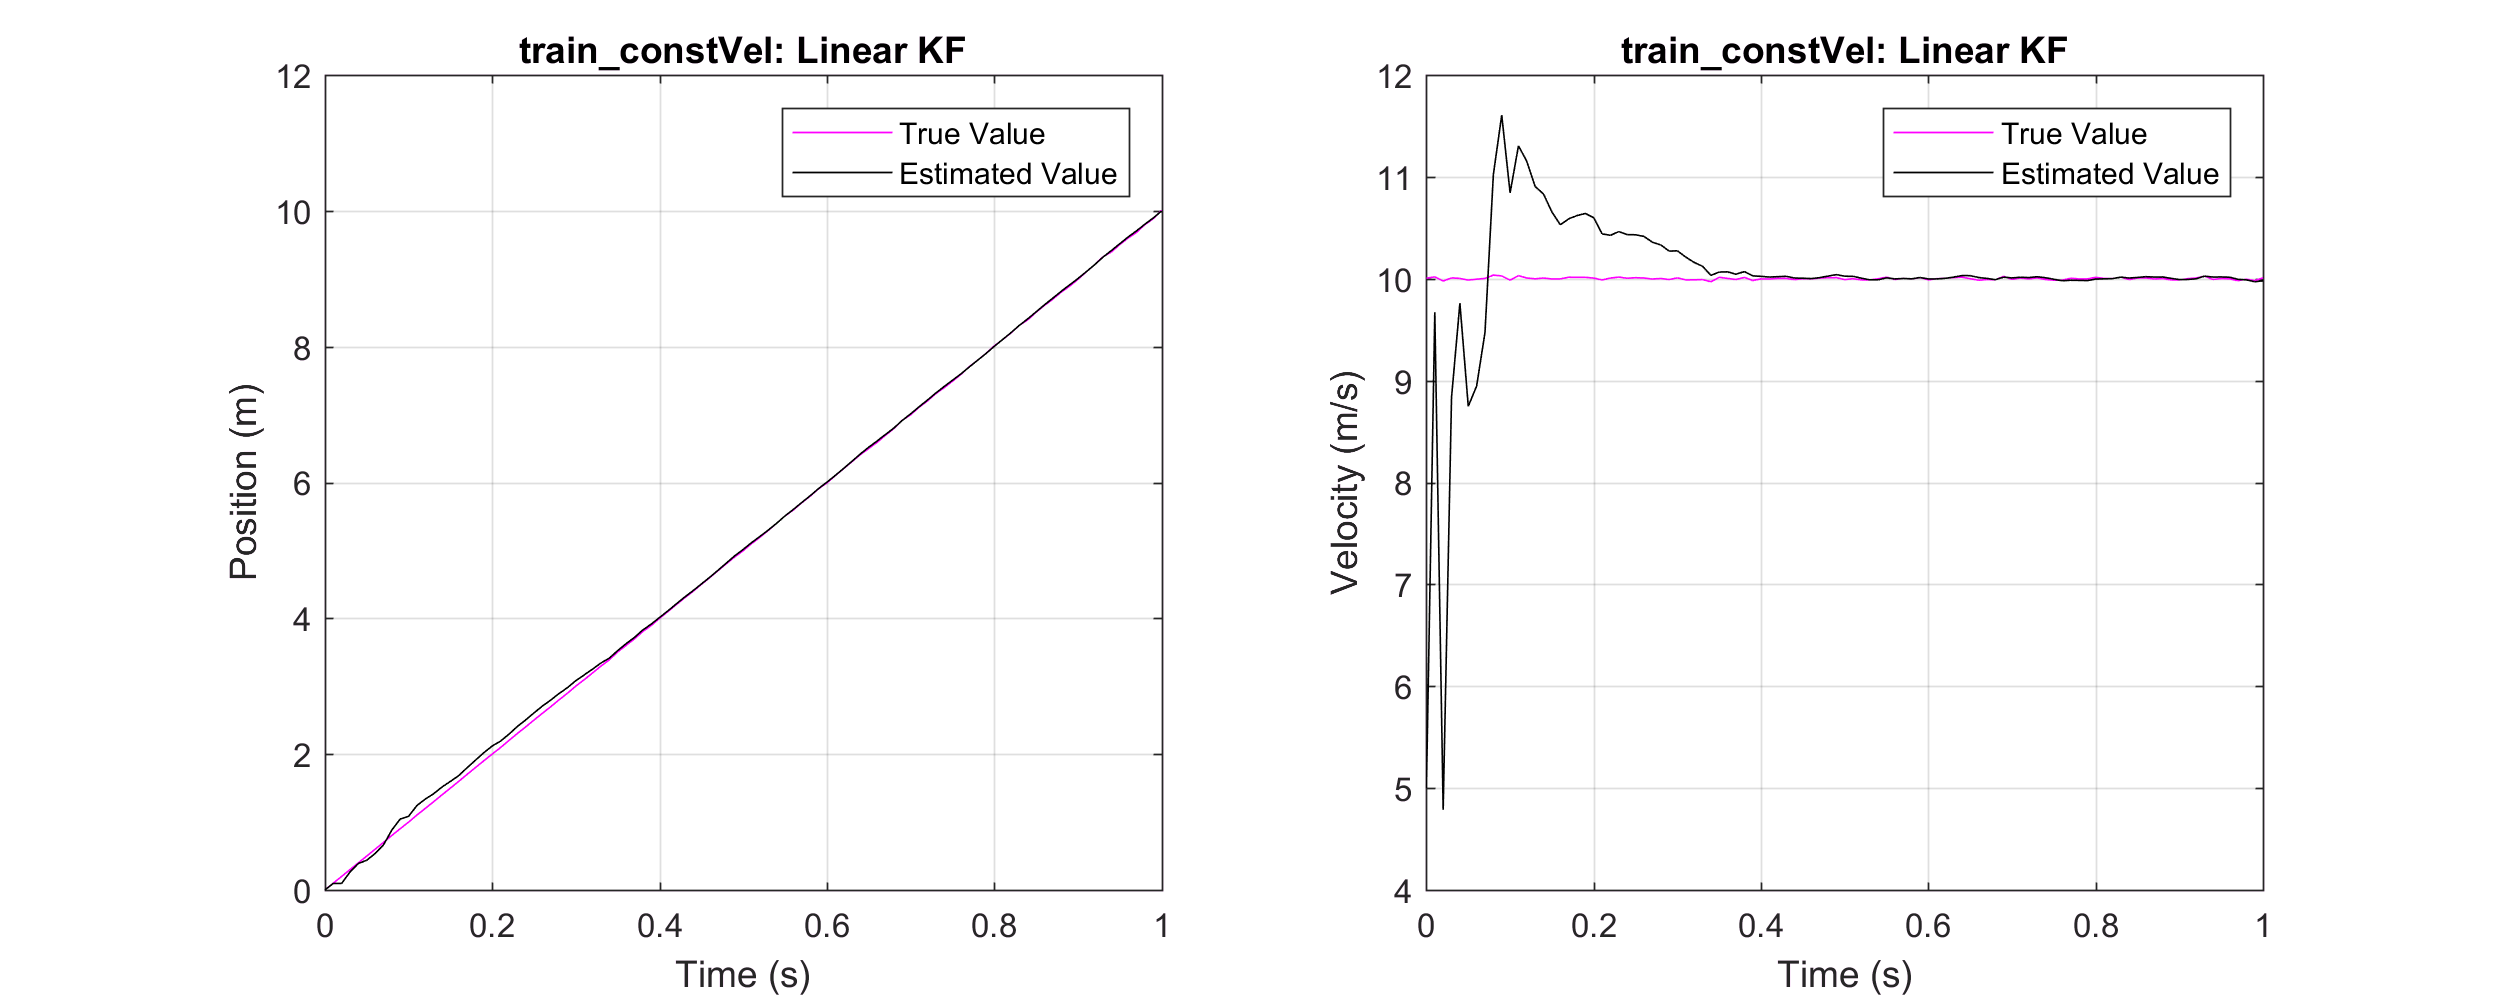

open('LinearKalmanFilter.fig')
set(gcf,'Position',[0 0 1000 400]);

After initially having poor estimates of velocity, due to our erroneous initial condition for velocity, the filter converges at roughly 0.4 seconds, and tracks the states of the system very accurately thereafter. I think this is pretty astonishing, and I hope that this motivates you to want to look under the cover and understand how Kalman filters work and how to use them. This will be the focus of the rest of this tutorial, starting with the linear Kalman filter, which was utilised so effectively in the above example.

# Linear Kalman Filter (KF)

So, we have seen the power of the linear Kalman filter (KF). Let's look at the algorithm, understand the terminology and get to grips with how it all works from one time step to the next. I've presented the equations for the KF below, but for now, skim through them, and let's start off by introducing the terminology:

## Linear Kalman Filter (KF) Equations

**1: Compute the predicted state and covariance matrix:**

Computing the predicted state: $\hat{x}_{k|k-1} = F\hat{x}_{k-1|k-1$ 

Computing the predicted covariance matrix: $P_{k|k-1} = FP_{k-1|k-1}F^T + Q_k$

**2: Compute the predicted measurement, innovation covariance matrix, and Kalman gain:**

Computing the predicted measurement: $\hat{y}_{k|k-1} = Hx_{k|k-1}$

Computing the innovation covariance matrix: $S_k = HP_{k|k-1}H^T + R_k$

Computing the Kalman gain: $K_k = P_{k|k-1}H^TS_K^{-1}$

**3: Compute the posterior mean and covariance matrix:**

Computing the posterior state: $\hat{x}_{k|k} = \hat{x}_{k|k-1}  + K_k(y_k - \hat{y}_{k|k-1})$

Coimputing the covariance matrix: $P_{k|k} = P_{k|k-1} - K_kH_kP_{k|k-1}$

## Linear Kalman Filter (KF) Terminology

This algorithm may look complex, but it can be easily implemented in only 7 lines of code so don't be put off. Let's demistify it slightly now by understanding some of the terms:

- $x_{k|k-1}$: This is the predicted *state vecto*r for this new time step, $k$,  based on the information from the previous time step, $k-1$. Reread that sentence if you are confused about the subscript notation.

- $\hat{x}_{k|k}$: This is our estimate of the current state $x_{k|k}$, which is the output of the filter. *Calculating this accurately is the purpose of the Kalman Filter*. **During the first time step, this value is specified by us with our best guess for the initial state**. In the example above, we gave it a poor estimate, making it take longer for the state estimate to converge to a good value. In our example, we set an erroneous initial state estimate of: $\hat{x}_{0|0} = \left[ \begin{array}{c}
0\\
5
\end{array} \right]$

- $P$: This is known as the *covariance matrix*, which captures our uncertainty in the state estimate. This, combined with the estimated state give the probability distribution for the state of the system. **During the first time step, this value is specified by us, typically by simply setting the diagonal terms to the magnitude squared of the anticipated error in the corresponding state component**. If we are certain of the position in our example, but believe we could have up to 5 m/s error in velocity, we would set the matrix to be initially: $P_{0|0} = \left[ \begin{array}{cc}
0 & 0\\
0 & 5^2
\end{array} \right]$ 

The job of the Kalman filter is to build an accurate estimate of our system's state at each time step. This is captured by the system state estimate, $\hat{x}_{k|k}$, and the covariance matrix, $P_{k|k}$, which provides the uncertainty around that state. The diagonal terms provide the amount of uncorrelated uncertainty between the states, with the off-diagonal terms giving information as to the correlated uncertainty between the states. Try playing the with these values in the below piece of code and observe how the probability density function changes in the different graph axes.

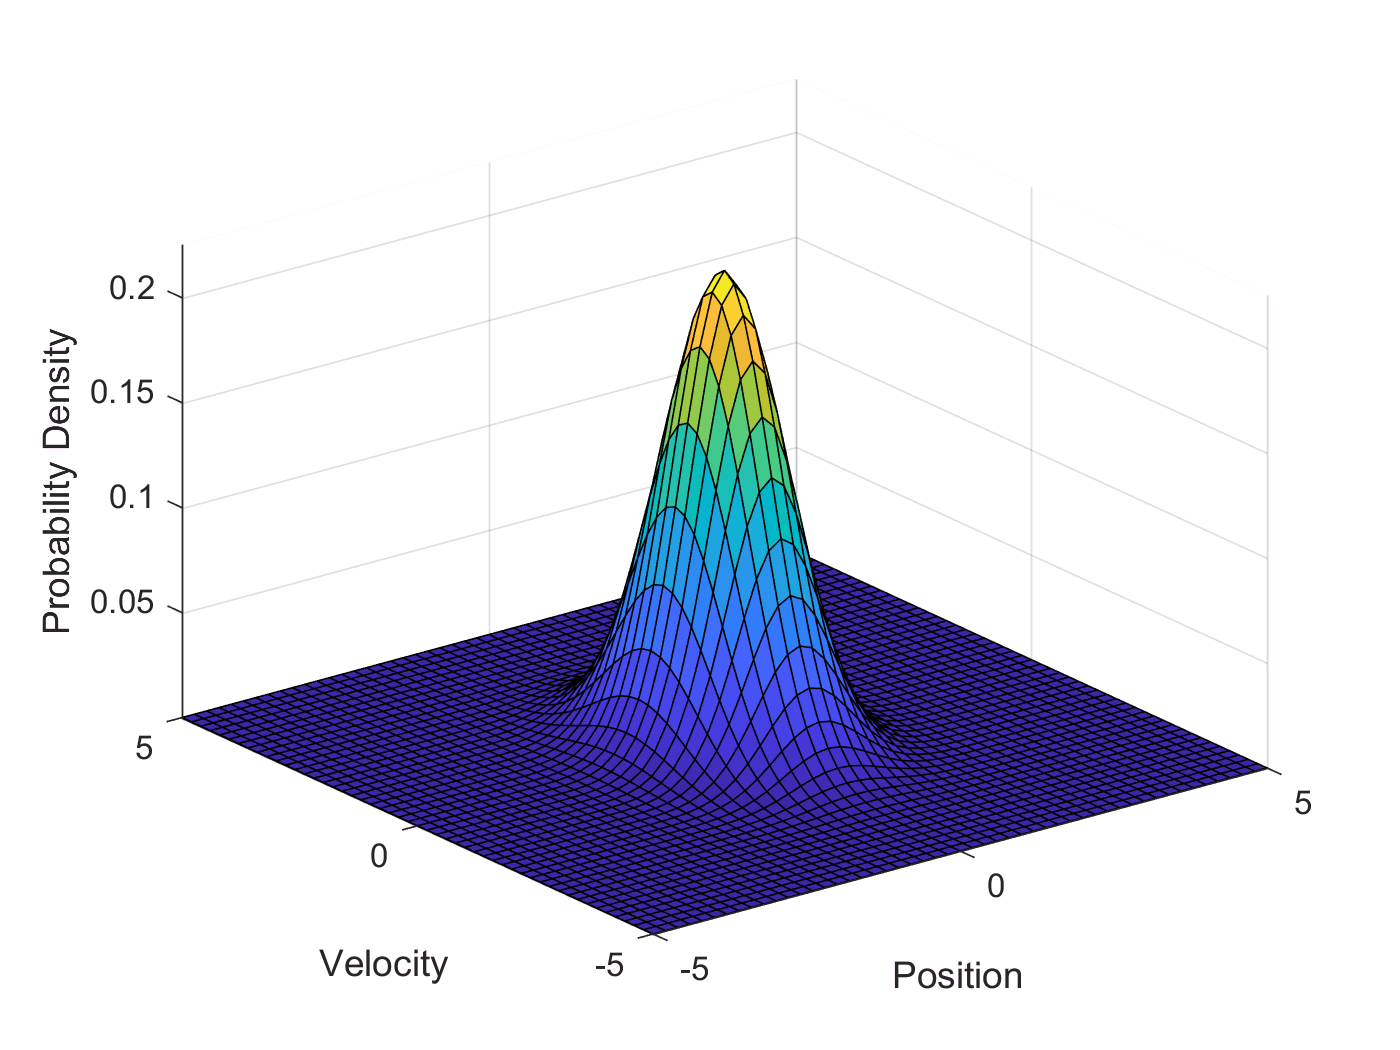

% Specify state mean and covariance parameters
stateMean = [0 0]; % This is our estimate of x
stateCovariance = [.5 0; % This is our matrix P
                    0 1];
% Build grid of points in order to observe Gaussian surface
pos = -5:.2:5; 
vel = -5:.2:5;
[X1,X2] = meshgrid(pos,vel);
% Calculate probabilities at gri points
probability = mvnpdf([X1(:) X2(:)],stateMean,stateCovariance);
probability = reshape(probability,length(vel),length(pos));
% Visualise surface
figure;
surf(pos,vel,probability);
axis([min(pos(:)) max(pos(:)) min(vel(:)) max(vel(:)) min(probability(:)) max(probability(:))])
xlabel('Position'); ylabel('Velocity'); zlabel('Probability Density');

The next parameters to introduce should be the matrices $F$ and $H$, which have already been discussed in our simple example. For a linear Kaman filter to be implemented, it is necessary for the state transistions and measurements to be able to be specified in this simple matrix form.

- $F$: This is known as the* state transitio**n matrix*, which captures our model of the system dynamics. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the next state vector.

- $H$: This is known as the *measurement matrix*, which captures our model of the measurements. This was introduced in our simple example above, acting as a linear mapping between the current state vector and the current measurement.

Next up, we should introduce Q and R in a litte more detail and how we set those up.

- $Q$: This is known as the *process noise covariance matrix*, which captures the amount of uncertainty which is contained in our state transition matrix model. **During the first time step, this value is specified by us with our best guess for the level of process noise, typically by simply setting the diagonal terms to the magnitude squared of the anticipated noise variance in the corresponding state component.**

- $R$: This is known as the measurement* noise covariance matrix*, which captures the amount of uncertainty which is contained in our measurement model. **During the first time step, this value is specified by us with our best guess for the level of measurement noise, typically by simply setting the diagonal terms to the magnitude squared of the anticipated noise variance in the corresponding state component.**

The above terms should now make much more sense, but there are still two more terms to introduce:

- $S$: This is known as the i*nnovation covariance matrix.*

- $K$: This is known as the *Kalman gain.*

In order to explain the meaning behind these terms and get a good understanding of the algorithm formulation, please refer to the excellent website by Tim Babb: [How A Kalman Filter Works in Pictures](http://www.bzarg.com/p/how-a-kalman-filter-works-in-pictures/).

Once you're comfortable with that, let's crack on with looking at the simple code. After setting up our absolute truth in the structure, s, we create our model of the system in the structure, d. From there, we move on each time step and follow the equations above in each of the seven lines of code. And that is the Kalman filter. If you can specify an accurate **linear** system behaviour and measurement with $F$ and $H$, and give an initial estimate of $\hat{x}$, $P$, $Q$, and $R$, you have all the ingredients to create a Kalman filter (KF).

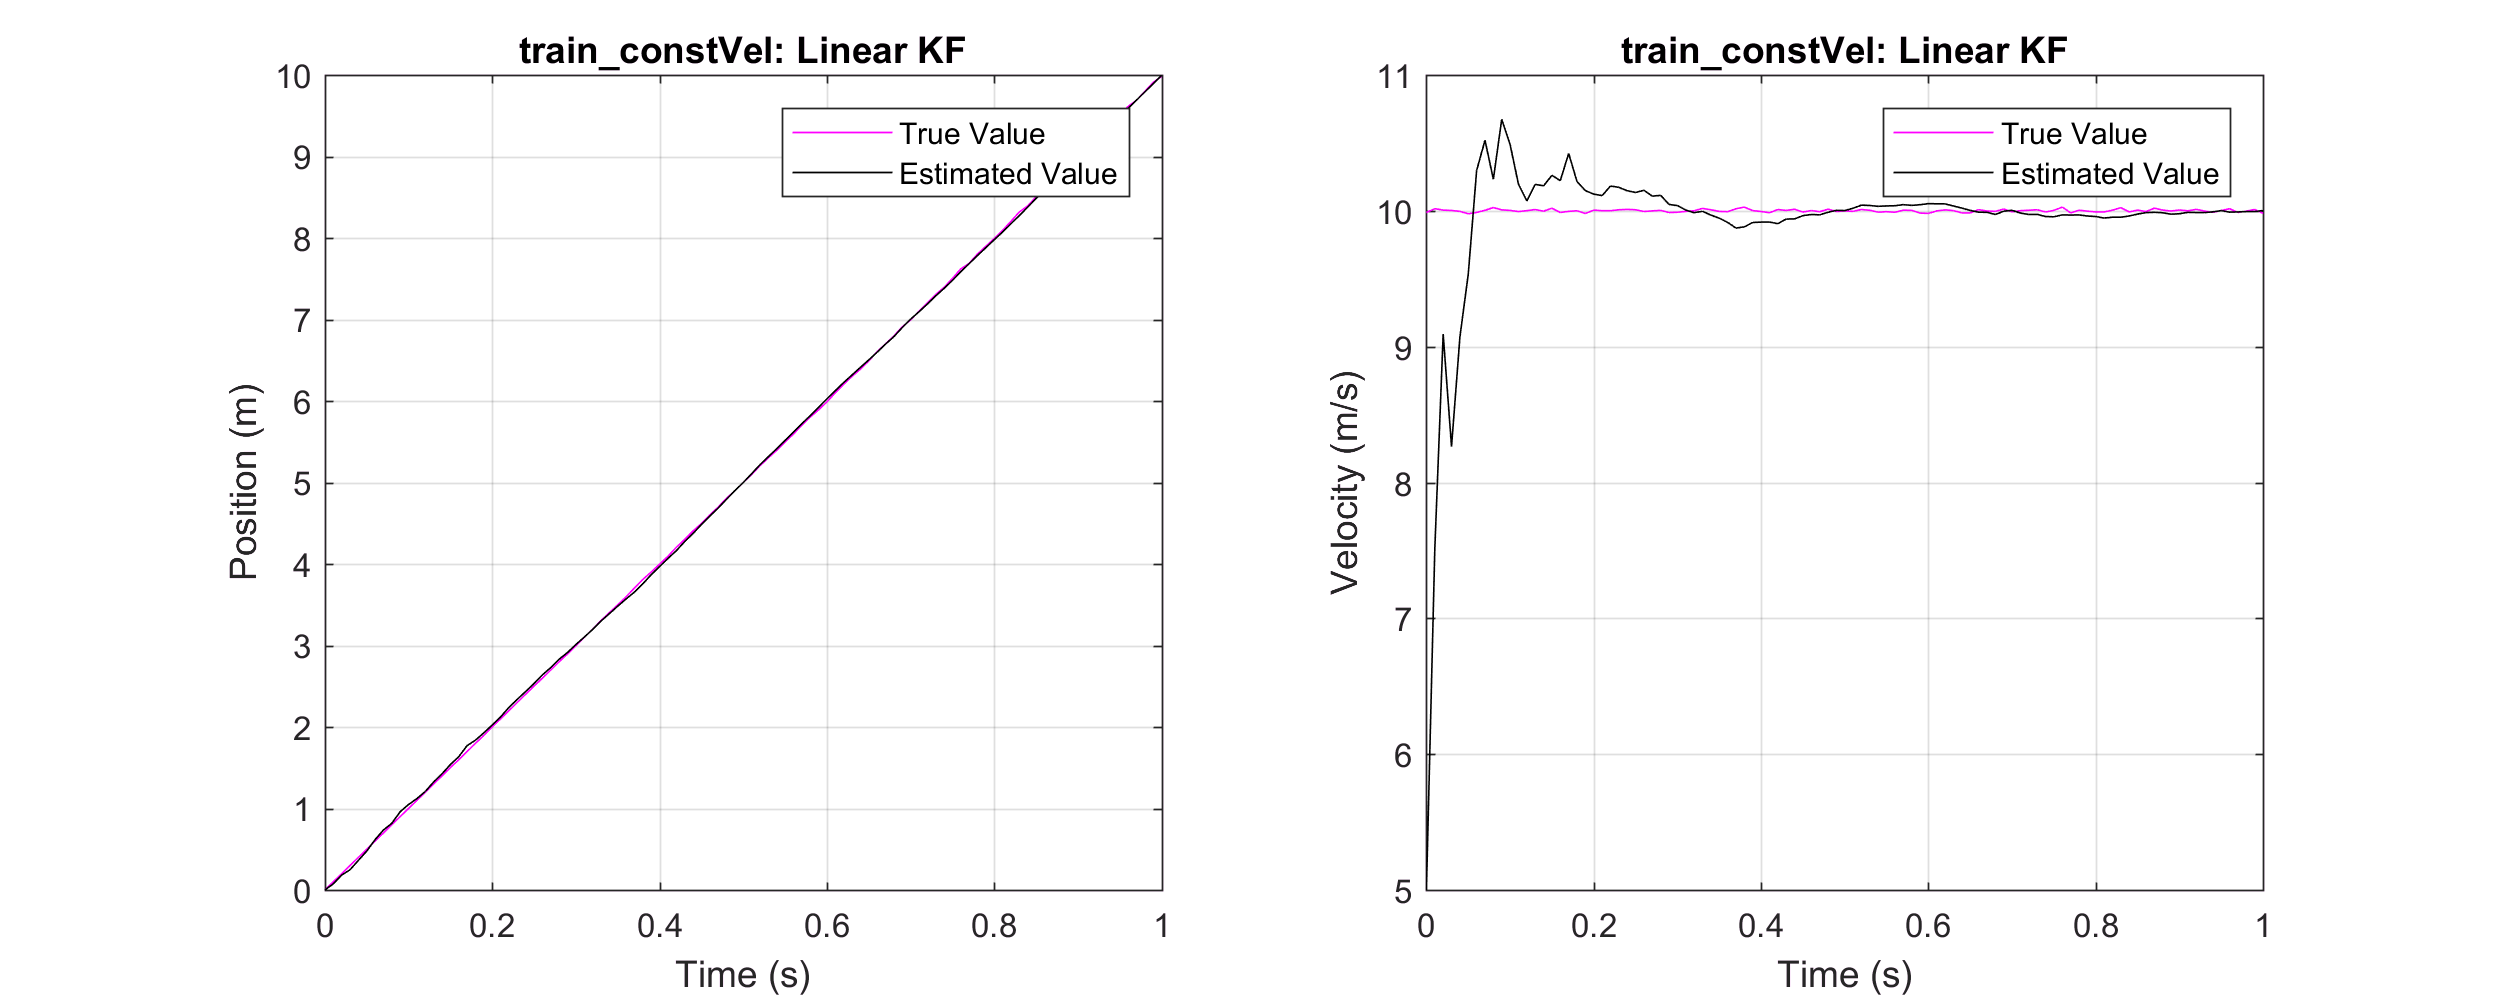

%% Set General Parameters %%%%%%%%%%%%%
NSamples=100; % Number of sample steps to simulate over
dt = 0.01; % Time step between samples, s

%% Ground Truth & Model %%%%%%%%%%%%%%%
s = train_constVel(NSamples,dt); % Set up a system of a train travelling at a constant velocity
d = model_train_constVelKF(s,dt); % Set up a KF model for the system

%% Linear Kalman Filter %%%%%%%%%%%%%%%
for k=2:NSamples+1
    % Compute the predicted mean, d.X1
    d.X1 = d.F * d.X(:,k-1);
    % Compute the predicted covariance matrix, d.P1
    d.P1 = (d.F * d.P * d.F') + d.Q;
    
    % Compute the predicted measurement, d.Y1
    d.Y1 = d.H * d.X1;
    % Compute the innovation covariance matrix, d.S
    S = (d.H * d.P1 * d.H') + d.R;
    % Compute the Kalman gain (K large -> more weight goes to measurement)
    K = (d.P1 * d.H' / S);
    
    % Compute the posterior mean, d.X
    d.X(:,k) = d.X1 + (K * (s.Y(:,k) - d.Y1));
    % Compute the covariance matrix, d.P
    d.P = d.P1 - (K * d.H * d.P1);
end

%% Plot resulting graphs %%%%%%%%%%%%%%
figure;
for i = 1:s.NState
    subplot(1,2,i);
    plot(s.t,s.X(i,:),'m');
    hold on; grid on;
    plot(s.t,d.X(i,:),'k');
    title(['Estimation Results: ' s.stateString{i}]);
    xlabel(s.tString);
    ylabel(s.stateString{i});
    legend('True Value','Estimated Value');
    t = title([s.modelString ': ' d.typeString]);
    set(t, 'Interpreter', 'none');
end
set(gcf,'Position',[0 0 1000 400]);

Take some time now to play around with the model and initialisation of the matrices in this example, but tweaking numbers in the function *model_train_constVelKF. *Specifically dedicating time to playing with the initial value of $\hat{x}$ and $P$ and observe the amount of time which the filter takes to converge.

Let's close of our analysis of the simple linear Kalman filter (KF). The Kalman filter has the following characteristics:

- It is very computationally light. It consists of simple matrix algebra. Therefore, as long as the number of states is small enough, this code should run on even a small microcontroller.

- Let's consider the systems which can be modelled with this KF. This filter can only be used on **linear systems**. If it is not possible to specify the system behaviour as $x_{k} = F.x_{k-1}$ with $F$ being a matrix containing purely numerical elements, then this type of Kalman filter is not appropriate for your application. The same is true for the matrix $H$.

- For this filter to work most effectively, the measurement noise, process noise, and posterior state density must be white, Gaussian noise. The further away from this idealisation that the real system gets, the worse the performance will be.

What tends to be the biggest problem with real life applications is that we regularly have to deal with non-linearity. If we still have Gaussian noise profiles but we have a non-linear system, attention should be turned to the Extended Kalman Filter (EKF) and Unscented Kalman Filter (UKF).

# Extended Kalman Filter (EKF)

The Extended Kalman Filter is a wonderfully-logical next step for the Kalman filter when have to start dealing with non-linearity in our system. The underlying method with the Extended Kalman Filter is